# 01 Hands On: Discrete Systems - 1D spring system - Part 1

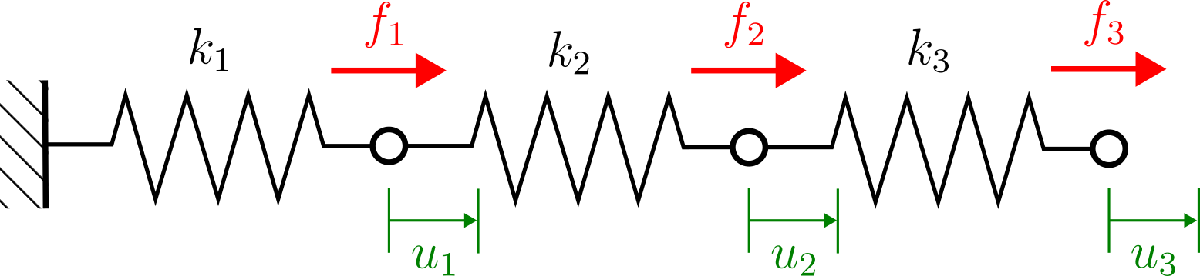

**Given quantities:**

- 
$$k_1=20~\frac{\text{N}}{\text{m}}, \quad k_2=15~\frac{\text{N}}{\text{m}}, \quad k_3 = 10~\frac{\text{N}}{\text{m}}$$


- 
$$f_1 = 0.5~\text{N}, \quad f_2 = 1~\text{N},\quad f_3=1.2~\text{N}$$


clear all; clc; close all;

% Given quantities
k1 = 20;    % [N/m]
k2 = 15;    % [N/m]
k3 = 10;    % [N/m]

f1 = 0.5;   % [N]
f2 = 1;     % [N]
f3 = 1.2;   % [N]

% Stiffness matrices
K1 = [  20, -20, 0, 0;
        -20, 20, 0, 0;
        0, 0, 0, 0;
        0, 0, 0, 0];

K2 = [  0, 0, 0, 0;
        0, 15, -15, 0;
        0, -15, 15, 0;
        0, 0, 0, 0];

K3 = [  0, 0, 0, 0;
        0, 0, 0, 0;
        0, 0, 10, -10;
        0, 0, -10, 10];

K = K1 + K2 + K3

K =     20   -20     0     0
   -20    35   -15     0
     0   -15    25   -10
     0     0   -10    10


% Force vector
f = [f1; f2; f3]

f =     0.5000
    1.0000
    1.2000


% Solution of the system
u = K(2 : end, 2 : end) \ f

u =     0.1350
    0.2817
    0.4017


To visualize the result, we make use of the `plot()` function. The function takes two arguments `x `and `y`, representing x- and y-coordinates of points in a plane. If `x` and `y` are arrays, the points are connected by straight lines. 

In order to plot the 1D spring system, we define the position of the nodes, assuming a unit length and a vertical position of 0 for each spring.

u   = [0; u];           % [m], deformations including u0
x0  = transpose(0:1:3)  % [m], nodal positions in undeformed state

x0 =      0
     1
     2
     3


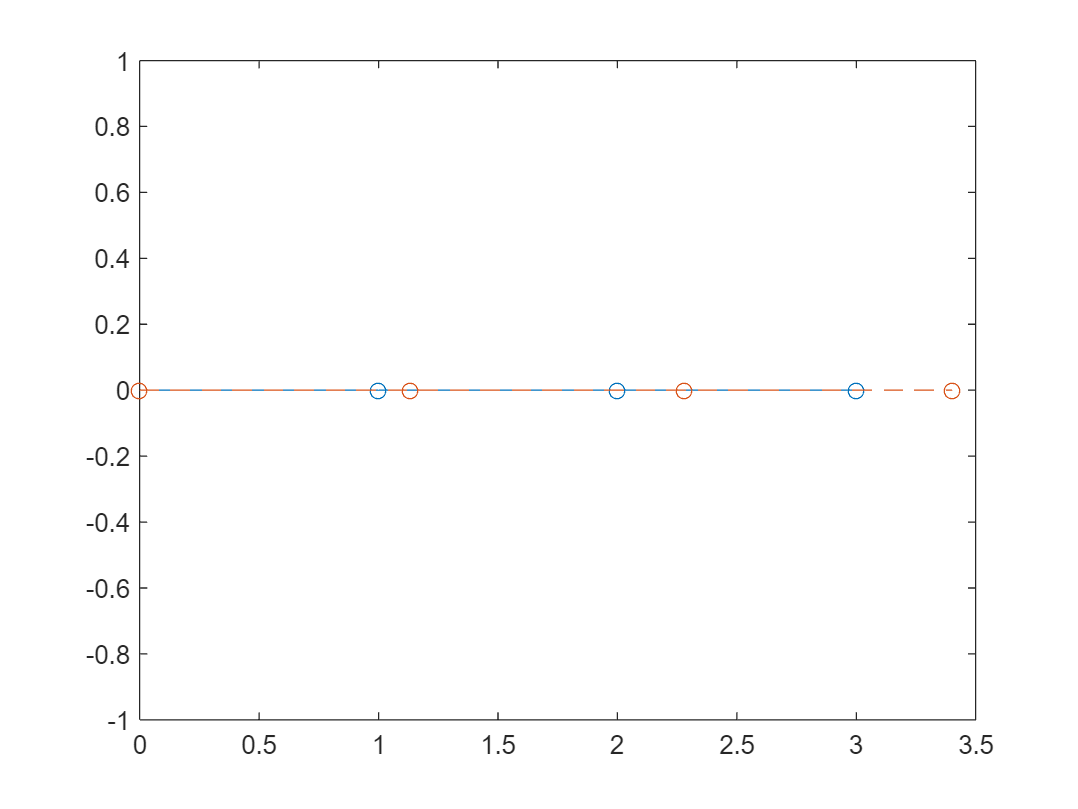

y0  = zeros(4,1);       % [m], vertical position of the nodes

% Plot undeformed system
plot(x0, y0, Marker='o'); hold on

% Impose deformation on x0 and plot deformed system
plot(x0 + u, y0, LineStyle='--', Marker='o')